# **利用 quiver 绘制电力线**

## **一、解析法绘制点电荷对的电力线**

**        以两点电荷系统为例，场点***** P*****(*****x*****,*****y*****)的电势（如果仅仅为了绘制电力线,可以不考虑系数**$q_1 /4\pi \varepsilon$**）可表示为：**


$$\phi =\frac{1}{\sqrt{(x+a)^2 +y^2 }}+\frac{Q^* }{\sqrt{(x-a)^2 +y^2 }}$$


**其中，两个点电荷分别位于**$(-a,0)$**，**$(a,0)$**，**$$$Q ^ { * } = q _ { 2 } / q _ { 1 }$$$**，则由**$$$E = - \nabla \phi$$$**得到的场强E在xOy平面只有两个分量：**


$$$$E _ { x } = - \frac { \partial \phi } { \partial x } , \quad E _ { y } = - \frac { \partial \phi } { \partial y }$$$$


**代入两式可得：**


$$$$\left\{ \begin{array} { l } { E _ { x } = \frac { x + a } { [ ( x + a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } + Q ^ { * } \frac { x - a } { [ ( x - a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } } \\ { E _ { y } = \frac { y } { [ ( x + a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } + Q ^ { * } \frac { y } { [ ( x - a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } } \end{array} \right.$$$$


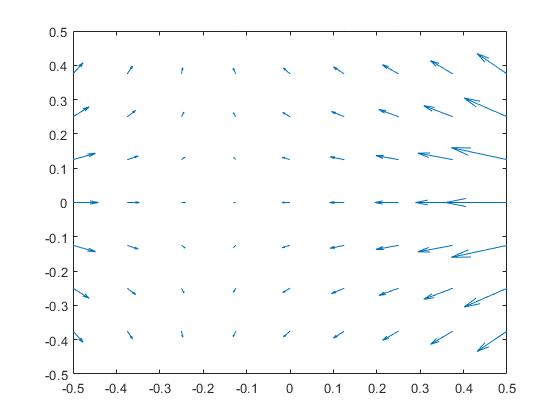

clear
clc
figure
a=1;
Q=2;
x=(-a/2:.125:a/2);
y=(-a/2:.125:a/2);
[X,Y] = meshgrid(x,y);            %设置网格区域
EX=(X+a)./(Y.^2+(X+a).^2).^(3/2)+Q*(X-a)./(Y.^2+(X-a).^2).^(3/2);   %电场强度x分量；
EY=(Y)./(Y.^2+(X+a).^2).^(3/2)+Q*(Y)./(Y.^2+(X-a).^2).^(3/2);   %电场强度y分量
quiver(X,Y,EX,EY);               %绘制电力线
axis([-a/2 a/2 -a/2 a/2]);                  %设置显示范围 
set(gcf,'Visible','on');   	    %强制图片弹出显示

## **二、解析法绘制点电荷对的电力线**

**        既然已知电势函数的分布，因此也可以利用数值方法计算梯度得到电场强度，然后再利用quiver 函数绘制电力线。与前面的解析方法相比，编制程序时仅仅需要电势函数，所以更加简洁。程序如下所示。为了与上面的结果有差异，程序中还特地绘制了相应的4条等势线。**

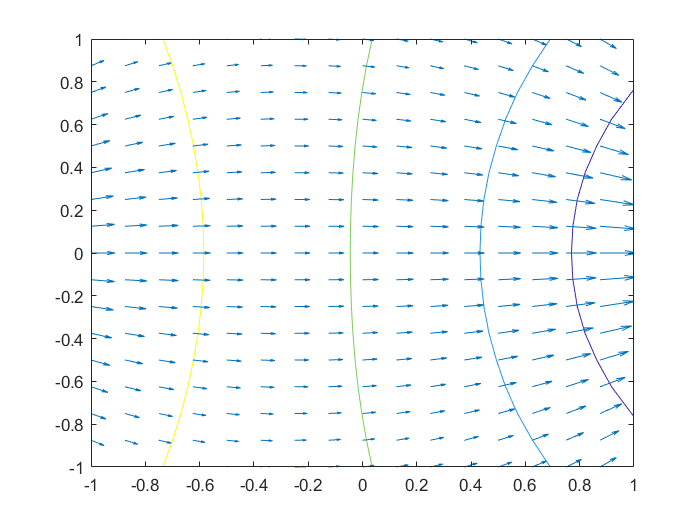

clear
clc
figure
a=2;
Q=-2;
x=(-a/2:.125:a/2);
y=(-a/2:.125:a/2);
figure
[X,Y] = meshgrid(x,y);            %设置网格区域
Phi =(1./sqrt(Y.^2+(X+a).^2)+Q*1./sqrt(Y.^2+(X-a).^2));    %电势函数的表达式
[DX,DY] = gradient(-Phi); 	%数值计算电势的负梯度，即电场强度，并存储在DX、DY中
contour(X,Y,Phi,4);     	%绘制等势线，一共4条
hold on;               	%告诉MATLAB使用叠加绘图模式，不要覆盖前面的图像
quiver(X,Y,DX,DY);     	%绘制电力线，并与前面的等势线叠加在一幅图中
axis([-a/2 a/2 -a/2 a/2]);                  %设置显示范围 
set(gcf,'Visible','on');   	    %强制图片弹出显示

## **三、解析法绘制点电荷对的电力线**

**        对于无限长的带电直导线，其对应的电势分布为**


$$\phi =-\frac{\rho_l }{2\pi \varepsilon_0 }\textrm{lnr}+c=-\frac{1}{4\pi \varepsilon_0 }\ln (x^2 +y^2 )+c$$


**其中，**$\rho_l$**是线电荷密度；**$c$**是与电势参考点相关的常数。不妨设置 **$c=0$**，且忽略系数**$q_1 /4\pi \varepsilon$**（该系数不影响电力线的形状和分布），则可以用如下程序绘制得到相应的电力线分布。**

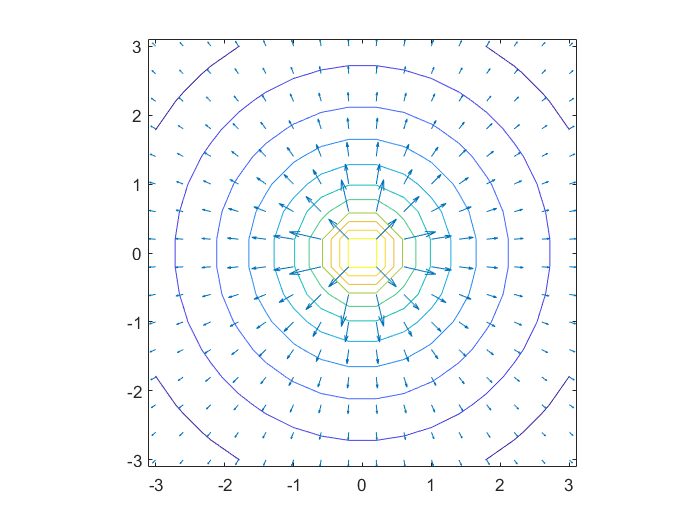

[X,Y] = meshgrid(-3:.4:3,-3:.4:3);        	%设置绘制区域的网格
phi = -log(X.^2 +Y.^2);                	%给出电势的表达式，忽略系数
[EX,EY] = gradient(-phi,.4,.4);          	%利用数值方法求电势的负梯度，得到电场强度
contour(X,Y,phi);                    	%绘制等势线
hold on                             	%叠加绘图模式，后面绘制的图与前面的图叠加
quiver(X,Y,EX,EY);                   	%在网格中绘制电力线
set(gcf,'Visible','on');   	    %强制图片弹出显示
axis image;                         	%x、y方向等比例显示，不做拉伸、压缩处理